# 1dof free damped

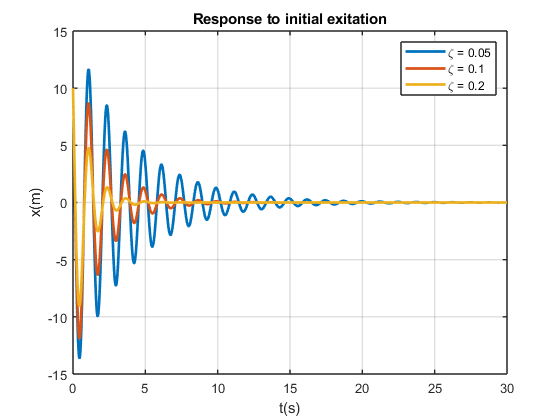

close all
clear all
clc

wn = 5; %Natural frecuency
zeta = [0.05;0.1;0.2]; %Damiping ratios
x0 = 10;
v0 = 60; %Initial Velocity
to = 0; %initial time
deltat = 0.01; %time step
tf = 30; %Final time

t = 0:deltat:tf;

for i = 1:length(zeta)
    wd = sqrt(1-zeta(i)^2)*wn; %Damped frecuency
    x = exp(-zeta(i)*wn*t).*(((zeta(i)*wn*x0-v0)/wd)*sin(wd*t) + x0*cos(wd*t));
    plot(t,x,'LineWidth',2,'DisplayName',['\zeta = ',num2str(zeta(i))])
    hold on
end

title('Response to initial exitation')
grid on
xlabel('t(s)')
ylabel('x(m)')
legend();

## Overdamped

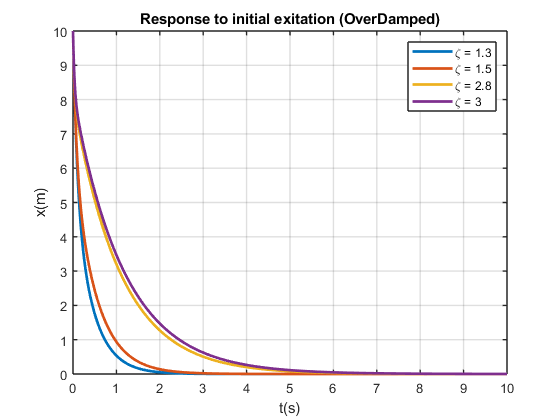

zeta = [1.3,1.5,2.8,3.0];
tf = 10; %Final time

t = 0:deltat:tf;

figure
for i = 1:length(zeta)
    wd = sqrt(1-zeta(i)^2)*wn; %Damped frecuency
    x = exp(-zeta(i)*wn*t).*(((zeta(i)*wn*x0-v0)/wd)*sin(wd*t) + x0*cos(wd*t));
    plot(t,x,'LineWidth',2,'DisplayName',['\zeta = ',num2str(zeta(i))])
    hold on
end

title('Response to initial exitation (OverDamped)')
grid on
xlabel('t(s)')
ylabel('x(m)')
legend();

## Comparisons

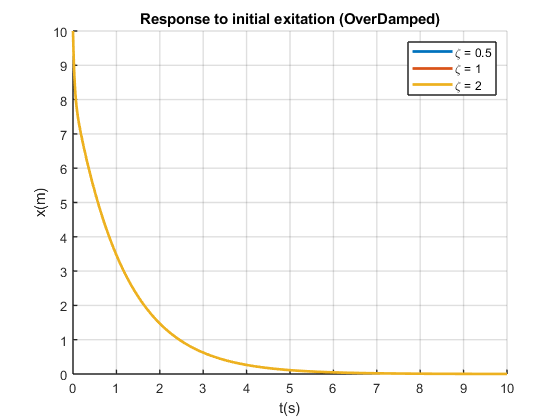

omega_n = 5;
zeta_values = [0.5,1,2];
figure
hold on
for i=1:length(zeta_values)
    zeta = zeta_values(i);    
    if zeta < 1
        %Undamped case
        omega_d = omega_n * sqrt(1 - zeta^2);
        A = x0;
        B = (v0 + zeta * omega_n * x0) / omega_d;
        x_t = exp(-zeta * omega_n * t) .* (A*cos(omega_d*t) + B *sin(omega_d*t));
    elseif zeta ==1
        %critically damped
        A = x0;
        B = v0 + omega_n * x0;
        x_t = (A + B*t).*exp(-omega_n*t);
    else
        %Damped case
        omega_d = omega_n*sqrt(zeta^2-1);
        A = (v0 + (zeta-1)*omega_n*x0)/(2*omega_n);
        B = (v0 + (zeta+1)*omega_n*x0)/(2*omega_n);
        x_t =  A*exp(-(zeta-1) * omega_n * t) + B*exp(-(zeta+1) * omega_n * t);
    end
    plot(t,x,'LineWidth',2,'DisplayName',['\zeta = ',num2str(zeta)])
end

title('Response to initial exitation (OverDamped)')
grid on
xlabel('t(s)')
ylabel('x(m)')
legend();

## Secod order

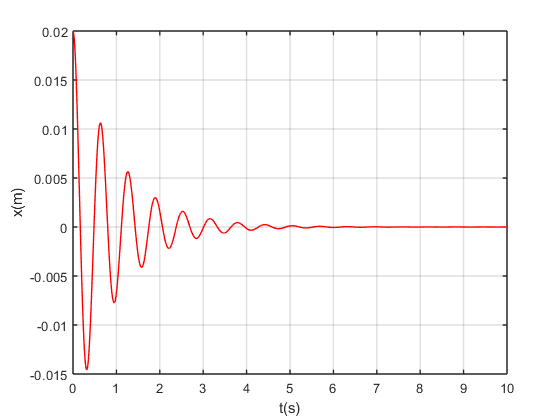

tspan=0:0.01:10;
y0=[0.02;0];

[t,y]=ode45('Free_Damped',tspan,y0);
figure
plot(t,y(:,1),'r') %First column disdplacemnt, second speed
xlabel('t(s)')
ylabel('x(m)')
grid on

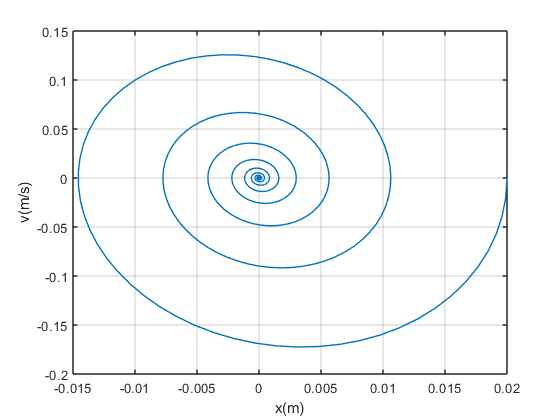


figure
plot(y(:,1),y(:,2)) %Displament 
xlabel('x(m)')
ylabel('v(m/s)')
grid on

## vAriation with Zeta

zeta=0.1:0.1:0.5;
for i=1:length(zeta)
    [t,y]
end


## Force Virbrations

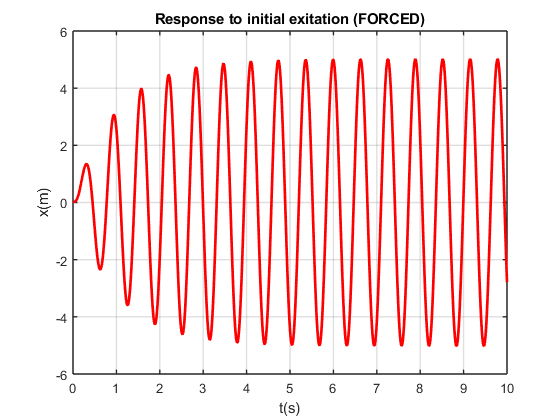

tspan=0:0.01:10;
y0=[0.02;0];

[t,y] = ode45('forced',tspan,y0);
figure
plot(t,y(:,1),'r',"LineWidth",2) %First column disdplacemnt, second speed
xlabel('t(s)')
ylabel('x(m)')
grid on
title('Response to initial exitation (FORCED)')